# Lab 7

Jessie Li // November 8, 2023

## 1

L = 50;
D = 8.5 * 1e7;
S = 100;
q = 1000;

% Decompose y'' = f(x, y, y') into a linear system
F = @(z, x) [z(2); 
             (S/D * z(2) + q*x / (2*D) * (x-L) * z(1)) * (1 + z(2)^2) ^ 1.5];


% Endpoints, x = a and x = b
a = 0;
b = 50;

% Boundary conditions, y(a) and y(b)
ya = 0;
yb = 0;

% Parameters for Newton's method
max_iterations = 20;
tolerance = 1e-14;

% Parameters for 4-Step Adams Predictor-Corrector
n = 5000;
h = (b-a)/n; % = 0.01

% Results
result_message = '';
newton_errors = zeros(1, max_iterations);

% Initial guess for y'(a)
u = -1.5;

% δf/δy 
df_dy = @(w, x) q*x / (2*D) * (x-L) * (1 + w(2)^2) ^ 1.5;

% δf/δy'
df_dydt = @(w, x) 3 * (1 + w(2)^2) ^ (1/2) * w(2) * (S/D * w(2) ...
        + q*x / (2*D) * (x - L) * w(1)) + ((1 + w(2)^2) ^ 1.5) * S/D;

% Decompose g'' = δf/δy * g + δf/δy' * g'
G = @(v, w, x) [v(2); 
                df_dy(w, x) * v(1) +  df_dydt(w, x) * v(2)];


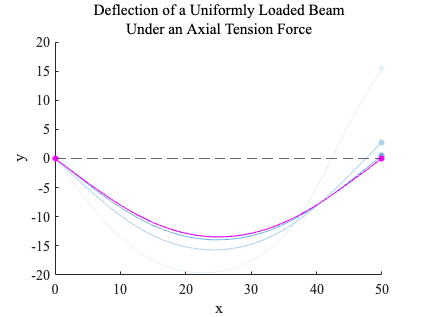

xx = a : h : b;

figure
gradient_style(9)
hold on

yline(0, '--')

for k = 1 : max_iterations 
    % fprintf(sprintf('%d: u = %.15f\n', k, u));

    % Solve y'' = f(x, y, y') with y(a) = α, y'(a) = u0 for z1(b, u_n)
    w = zeros(2, n + 1);      
    f = zeros(2, n + 1);

    % Solve g'' = δf/δy * g + δf/δy' * g' with g(a) = 0, g'(a) = 1 for g(b, u_n)
    v = zeros(2, n + 1);
    g = zeros(2, n + 1);

    % Solve system to get z1(b, u) then δz1(b, u)/δu using 4-Step Adams Predictor-Corrector
    w(:, 1) = [ya; u];
    f(:, 1) = F(w(:, 1), a);

    v(:, 1) = [0; 1];
    g(:, 1) = G(v(:, 1), w(:, 1), a);

    % Compute the first three steps using RK4
    for i = 1 : 3
        t = a + (i-1) * h;

        % RK4 for [z1(x, u_n); z2(x, u_n)]
        f1 = F(w(:, i), t);
        f2 = F(w(:, i) + h/2 .* f1, t + h/2);
        f3 = F(w(:, i) + h/2 .* f2, t + h/2);
        f4 = F(w(:, i) + h .* f3, t + h);

        w(:, i+1) = w(:, i) + h/6 .* (f1 + 2 .* (f2 + f3) + f4);
        f(:, i+1) = F(w(:, i+1), t + h);

        % RK4 for [v1(x, u_n); v2(x, u_n)]
        g1 = G(v(:, i), w(:, i), t);
        g2 = G(v(:, i) + h/2 .* g1, w(:, i), t + h/2);
        g3 = G(v(:, i) + h/2 .* g2, w(:, i), t + h/2);
        g4 = G(v(:, i) + h .* g3, w(:, i), t + h);

        v(:, i+1) = v(:, i) + h/6 .* (g1 + 2 .* (g2 + g3) + g4);
        g(:, i+1) = G(v(:, i+1), w(:, i+1), t + h);
    end
        
    % 4-Step Adams Predictor-Corrector
    for i = 4 : n 

        t = a + i * h;

        % Predict w(i+1) with the Adams-Bashforth 4-step predictor
        w(:, i+1) = w(:, i) + h/24 .* (55 .* f(:, i) - 59 .* f(:, i-1) + 37 .* f(:, i-2) - 9 .* f(:, i-3));
        f(:, i+1) = F(w(:, i+1), t);

        v(:, i+1) = v(:, i) + h/24 .* (55 .* g(:, i) - 59 .* g(:, i-1) + 37 .* g(:, i-2) - 9 .* g(:, i-3));
        g(:, i+1) = G(v(:, i+1), w(:, i+1), t);

        % Correct w(i+1) with the Adams-Moulton 4-step corrector
        w(:, i+1) = w(:, i) + h/720 .* (251 .* f(:, i+1) + 646 .* f(:, i) - 264 .* f(:, i-1) + 106 .* f(:, i-2) - 19 .* f(:, i-3));
        f(:, i+1) = F(w(:, i+1), t);

        v(:, i+1) = v(:, i) + h/720 .* (251 .* g(:, i+1) + 646 .* g(:, i) - 264 .* g(:, i-1) + 106 .* g(:, i-2) - 19 .* g(:, i-3));
        g(:, i+1) = G(v(:, i+1), w(:, i+1), t);     
    end

    newton_errors(k) = abs(w(1, end) - yb);

    % Stop of error is less than tolerance
    if abs(w(1, end) - yb) < tolerance
        
        % Plot final solution for y(x)
        p = plot(xx, w(1, :), 'magenta');
        scatter(50, w(1, end), 'filled', 'MarkerFaceColor', 'magenta');

        result_message = sprintf('Found u = %.5f after %d iterations.', u, k);
        break;
    
    elseif k == max_iterations
        
        % Plot y(x)
        p = plot(xx, w(1, :));
        scatter(50, w(1, end), 'filled', 'MarkerFaceColor', get(p, 'Color'));

        result_message = sprintf('Exceeded maximum number of iterations. Error: %f', abs(w(1, end) - yb));
        break;
    
    end

    % Plot y(x)
    p = plot(xx, w(1, :));
    scatter(50, w(1, end), 'filled', 'MarkerFaceColor', get(p, 'Color'));

    % Newton's method to update u
    u = u - (w(1, end) - yb) / v(1, end);

end

% Boundary conditions, y(a) and y(b)
scatter([0, 50], [0, 0], 'filled', 'MarkerFaceColor', 'magenta');
hold off

xlabel('x')
ylabel('y')
title({'Deflection of a Uniformly Loaded Beam', 'Under an Axial Tension Force'}, 'FontWeight', 'normal', 'FontSize', 18)


fprintf(result_message);

Found u = -0.83467 after 8 iterations.

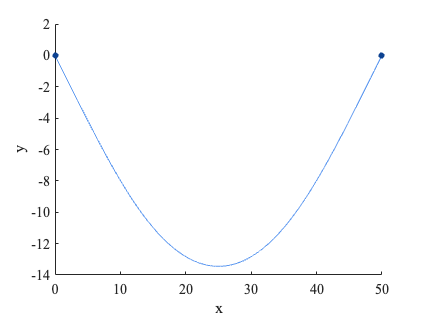

% Final solution for y as a function of x
xx = 0 : h : 50;

figure
default_style()

hold on
% Plot y(x)
plot(xx, w(1, :));

% Boundary conditions, y(a) and y(b)
scatter([0, 50], [0, 0], 'filled');
hold off

xlabel('x')
ylabel('y')

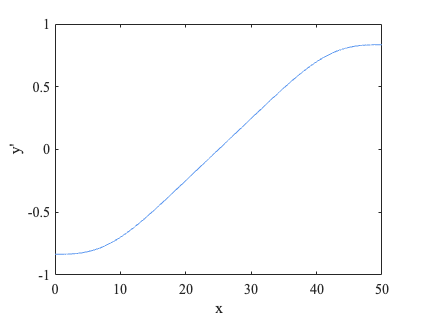

% Final solution for y' as a function of x
figure
default_style()

% Plot y'(x)
plot(xx, w(2, :));

xlabel('x')
ylabel('y''')

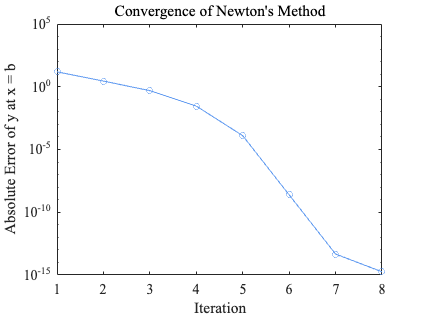

% Convergence of Newton's method
figure
default_style()

% Plot error at x = b v. iteration (Newton's)
semilogy(1 : k, newton_errors(1 : k), '-o')

xlabel('Iteration')
ylabel('Absolute Error of y at x = b')
title('Convergence of Newton''s Method', 'FontWeight', 'normal')

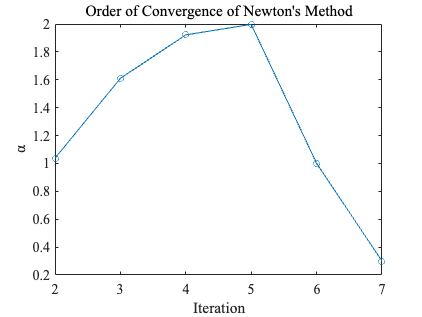

% Order of convergence of Newton's method
alpha = zeros(1, k - 2);

for i = 2 : k-1
    alpha(i-1) = (log(newton_errors(i+1)) - log(newton_errors(i))) / ...
                 (log(newton_errors(i)) - log(newton_errors(i-1)));
end

figure
plot(2 : k-1, alpha, '-o')

xlabel('Iteration')
ylabel('α')
title('Order of Convergence of Newton''s Method', 'FontWeight', 'normal', 'FontSize', 18)

% Truncation error of 4-Step Adams Predictor-Corrector
a = 0;
b = 50;

step_sizes = [10, 1, 0.1, 0.01, 0.001, 0.0001];
w = zeros(size(step_sizes, 2) * 2, (b - a) / min(step_sizes));

figure
gradient_style(size(step_sizes, 2))

% Find 4-Step Adams solution for y(x) and y'(x)
% for each step size with final u

for i = 1 : 2 : size(step_sizes, 2) * 2 - 1
    h = step_sizes((i + 1) / 2);
    n = (b - a) / h;
    w(i:i+1, 1:n+1) = adams4(F, a, b, h, [ya; u]);
end


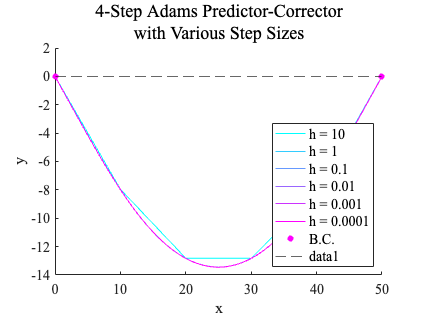

% Plot y(x) for each step size
figure
gradient_style_cool(size(step_sizes, 2))

hold on
yline(0, '--')

for i = 1 : 2 : size(step_sizes, 2) * 2 - 1
    h = step_sizes((i+1)/2);
    xx = a : h : b;
    n = (b-a)/h;
    
    p = plot(xx, w(i, 1:n+1), 'DisplayName', sprintf('h = %.4g', h));
end

% Boundary conditions, y(a) and y(b)
scatter([0, 50], [0, 0], 'filled', 'MarkerFaceColor', get(p, 'Color'), 'DisplayName', 'B.C.');
hold off

xlabel('x')
ylabel('y')
title({'4-Step Adams Predictor-Corrector', 'with Various Step Sizes'}, 'FontWeight', 'normal', 'FontSize', 18)

legend('Location', 'southeast', 'FontSize', 14)

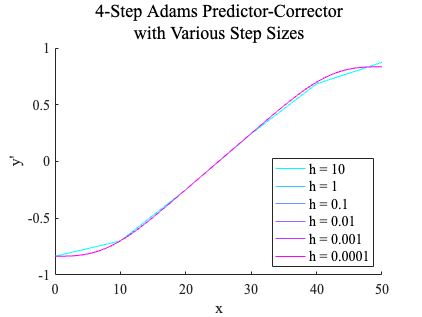

% Plot y'(x) for each step size
figure
gradient_style_cool(size(step_sizes, 2))

hold on
for i = 2 : 2 : size(step_sizes, 2) * 2
    h = step_sizes(i/2);
    xx = a : h : b;
    n = (b-a)/h;
    
    plot(xx, w(i, 1 : n+1), 'DisplayName', sprintf('h = %.4g', h))
end

xlabel('x')
ylabel('y''')
title({'4-Step Adams Predictor-Corrector', 'with Various Step Sizes'}, 'FontWeight', 'normal', 'FontSize', 18)

legend('Location', 'southeast', 'FontSize', 14)

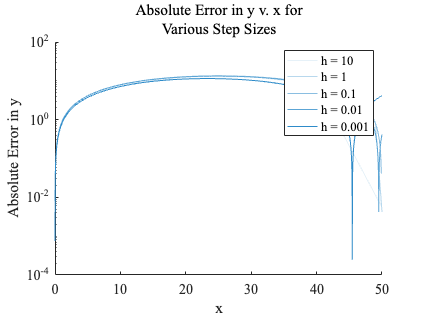

% For each step size, plot error in y v. x assuming smallest step size is exact solution
figure
gradient_style(size(step_sizes, 2))

hold on
for i = 1 : 2 : size(step_sizes, 2) * 2 - 2
    h = step_sizes((i+1)/2);
    xx = a : h : b;
    n = (b-a)/h;

    error = abs(w(i, :) - w(end-1, :));
    plot(xx, error(1 : n+1), 'DisplayName', sprintf('h = %.4g', h))
end
hold off

set(gca, 'YScale', 'log')

xlabel('x')
ylabel('Absolute Error in y')
title({'Absolute Error in y v. x for', 'Various Step Sizes'}, 'FontWeight', 'normal')

legend()

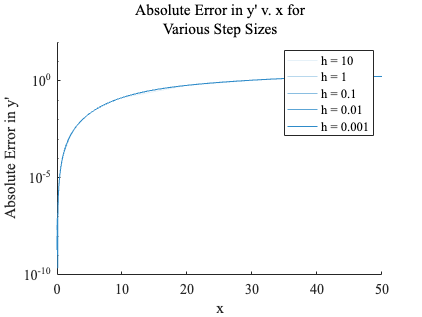

% Error in y' v. x for each step size
figure
gradient_style(size(step_sizes, 2))

hold on
for i = 2 : 2 : size(step_sizes, 2) * 2 - 1
    h = step_sizes(i/2);
    xx = a : h : b;
    n = (b-a)/h;

    error = abs(w(i, :) - w(end, :));
    plot(xx, error(1 : n+1), 'DisplayName', sprintf('h = %.4g', h))
end
hold off

set(gca, 'YScale', 'log')

xlabel('x')
ylabel('Absolute Error in y''')
title({'Absolute Error in y'' v. x for', 'Various Step Sizes'}, 'FontWeight', 'normal')

legend()

% Plot error of y at x = b v. step size
figure
default_style()

errors_yb = zeros(size(step_sizes));

for i = 1 : 2 : size(step_sizes, 2) * 2 - 2
    h = step_sizes((i+1)/2);
    n = (b-a)/h;
    
    % errors_yb((i + 1) / 2) = abs(yb - w(i, n+1));
    errors_yb((i+1)/2) = abs(w(end-1, end) - w(i, n+1));
    errors_yb((i+1)/2)
end

ans = 0.0051

ans = 6.9147e-06

ans = 1.2185e-11

ans = 1.1294e-13

ans = 2.0664e-13

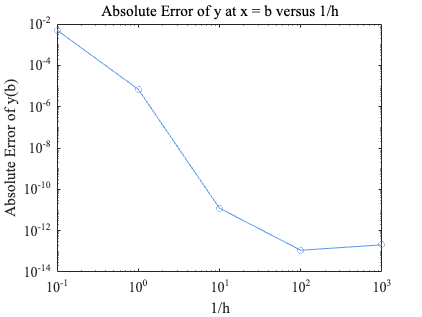


loglog(1 ./ step_sizes, errors_yb, '-o')

xlabel('1/h')
ylabel('Absolute Error of y(b)')
title({'Absolute Error of y at x = b versus 1/h'}, 'FontWeight', 'normal', 'FontSize', 18)

% Plot error of y' at x = b v. step size
figure
default_style()

errors_dyb = zeros(1, size(step_sizes, 2) - 1);

for i = 2 : 2 : size(step_sizes, 2) * 2 - 2
    h = step_sizes(i/2);
    n = (b-a)/h;

    % Assume smallest step size is "exact"
    errors_dyb(i/2) = abs(w(end, end) - w(i, n+1));
    errors_dyb(i/2)
end

ans = 0.0385

ans = 7.0459e-07

ans = 4.3814e-12

ans = 3.6082e-14

ans = 5.3291e-14

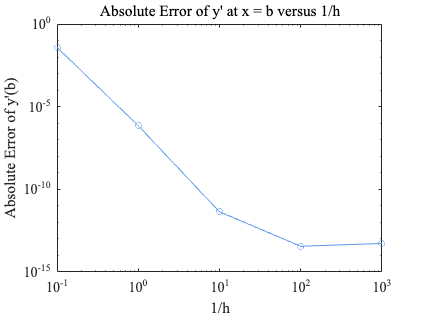


loglog(1 ./ step_sizes(1:end-1), errors_dyb, '-o')
set(gca, 'YScale', 'log')

xlabel('1/h')
ylabel('Absolute Error of y''(b)')
title({'Absolute Error of y'' at x = b versus 1/h'}, 'FontWeight', 'normal', 'FontSize', 18)

## 2

L = 1;
lambda2 = 2.7;
Ta = 37;
Tc = 37;
Ts = 32;

T_analytic = @(x) (Ts - Tc) .* sinh(sqrt(lambda2) .* x) ./ sinh(sqrt(lambda2) * L);

n_subintervals = [5, 10, 20, 40, 80, 160];
errors = zeros(1, size(n_subintervals, 2));

figure 
default_style()

hold on

% Plot analytic solution
xx = 0 : 1e-3 : L;
plot(xx, T_analytic(xx), 'magenta', 'LineWidth', 2, 'DisplayName', 'Analytic')

for j = 1 : size(n_subintervals, 2)
    n = n_subintervals(j) - 1;

    A = zeros(n, n);
    b = zeros(n, 1);
    h = L / (n + 1);

    for i = 1 : n
        A(i, i) = -(2 + h^2 * lambda2);
    
        if i < n
            A(i, i+1) = 1;
        end

        if i > 1
            A(i, i-1) = 1;
        end
    end
    
    % Boundary conditions
    b(1) = -(Tc - Ta);
    b(n) = -(Ts - Ta);

    % Solve the system for T = [T1 ... Tn]
    % T = A \ b;
    T = solve_tridiagonal(A, b);

    % Plot T v. x
    xx = 0 : h : L;
    TT = [(Tc - Ta) T.' (Ts - Ta)];

    plot(xx, TT, '--', 'LineWidth', 2, 'DisplayName', sprintf('N + 1 = %d', n + 1));

    % Calculate error
    errors(j) = max(abs(TT - T_analytic(xx)));
    max(abs(TT - T_analytic(xx)))

end

ans = 5.8826

ans = 7.6708

ans = 8.7575

ans = 9.3579

ans = 9.6735

ans = 9.8354

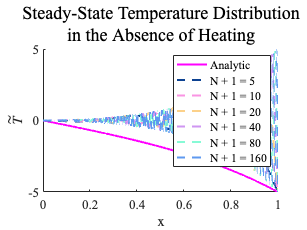


hold off

xlabel('x', 'Interpreter', 'latex')
ylabel('$\tilde{T}$', 'Interpreter', 'latex')
title({'Steady-State Temperature Distribution', 'in the Absence of Heating'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

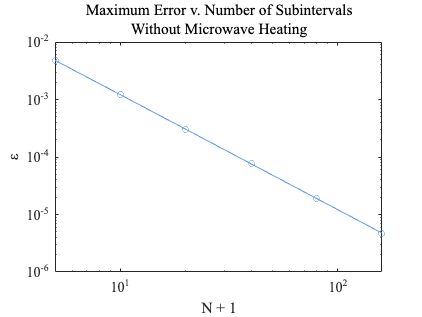

% Plot ε versus (N + 1) on a log-log scale
figure
default_style()

loglog(n_subintervals, errors, '-o')

ylabel('ε')
xlabel('N + 1')
title({'Maximum Error v. Number of Subintervals', 'Without Microwave Heating'}, 'FontWeight', 'normal', 'FontSize', 18)


% Centered difference approximations are O(h^2)
% --> Halving subinterval should decrease error by a factor of 4


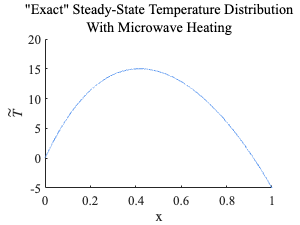

microwave_heating = 100;
gamma = 1 / L;

% Small step size to approximate the exact solution
n_subintervals_exact = 16000;
n = n_subintervals_exact - 1;

A = zeros(n, n);
b = zeros(n, 1);
h = L / (n + 1);

xx_exact = 0 : h : L;

for i = 1 : n
    A(i, i) = -(2 + h^2 * lambda2);
    
    if i < n
        A(i, i+1) = 1;
    end

    if i > 1
        A(i, i-1) = 1;
    end

    b(i) = -h^2 * microwave_heating * exp(gamma * (L - xx_exact(i+1)));
end

% Boundary conditions
b(1) = b(1) - (Tc - Ta);
b(n) = b(n) - (Ts - Ta);

% Solve the system for T = [T1 ... Tn]
% T = A \ b;
T = solve_tridiagonal(A, b);

% Plot T v. x
TT_exact = [(Tc - Ta) T.' (Ts - Ta)];

plot(xx_exact, TT_exact, 'DisplayName', sprintf('N + 1 = %d', n + 1));

xlabel('x', 'Interpreter', 'latex')
ylabel('$\tilde{T}$', 'Interpreter', 'latex')
title({'"Exact" Steady-State Temperature Distribution', 'With Microwave Heating'}, 'FontWeight', 'normal', 'FontSize', 18)

errors_heat = zeros(1, size(n_subintervals, 2));

figure 
default_style()

hold on
plot(xx_exact, TT_exact, 'Color', [0.7 0 1], 'DisplayName', '"Exact"', 'LineWidth', 2);

for j = 1 : size(n_subintervals, 2)
    n = n_subintervals(j) - 1;

    A = zeros(n, n);
    b = zeros(n, 1);
    h = L / (n + 1);

    xx = 0 : h : L;

    for i = 1 : n
        A(i, i) = -(2 + h^2 * lambda2);
    
        if i < n
            A(i, i+1) = 1;
        end

        if i > 1
            A(i, i-1) = 1;
        end

        b(i) = -h^2 * microwave_heating * exp(gamma * (L - xx(i+1)));
    end
    
    % Boundary conditions
    b(1) = b(1) - (Tc - Ta);
    b(n) = b(n) - (Ts - Ta);

    % Solve the system for T = [T1 ... Tn]
    % T = A \ b;
    T = solve_tridiagonal(A, b);

    % Plot T v. x
    TT = [(Tc - Ta) T.' (Ts - Ta)];

    plot(xx, TT, 'DisplayName', sprintf('N + 1 = %d', n + 1));

    % Calculate error
    errors_heat(j) = max(abs(TT - TT_exact(1 : n_subintervals_exact/n_subintervals(j) : end)));
    max(abs(TT - TT_exact(1 : n_subintervals_exact/n_subintervals(j) : end)))

end

ans = 0.1724

ans = 0.0435

ans = 0.0110

ans = 0.0027

ans = 6.8697e-04

ans = 1.7178e-04

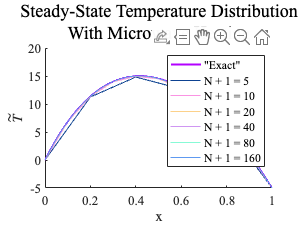

hold off

xlabel('x', 'Interpreter', 'latex')
ylabel('$\tilde{T}$', 'Interpreter', 'latex')
title({'Steady-State Temperature Distribution', 'With Microwave Heating'}, 'FontWeight', 'normal', 'FontSize', 18)

legend()

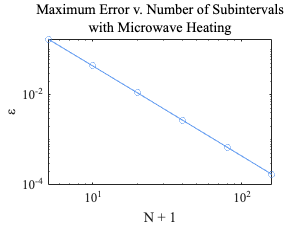

% Plot ε versus (N + 1) on a log-log scale
figure
default_style()

loglog(n_subintervals, errors_heat, '-o')

ylabel('ε')
xlabel('N + 1')
title({'Maximum Error v. Number of Subintervals', 'with Microwave Heating'}, 'FontWeight', 'normal', 'FontSize', 18)

function w = adams4(dy_dt, a, b, h, y0)
    %{
        A 4-step Adams-Bashforth/Adams-Moulton predictor corrector
        with a single correction.
        
        Input:
            f: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial conditions
    w = zeros(size(y0, 1), n + 1);
    f = zeros(size(y0, 1), n + 1);

    w(:, 1) = y0;
    f(:, 1) = dy_dt(y0, a);
    
    % Compute the first three (next) steps using RK4
    for i = 1:3
        t = a + (i-1) * h;

        f1 = dy_dt(y0, t);
        f2 = dy_dt(y0 + h/2 .* f1, t + h/2);
        f3 = dy_dt(y0 + h/2 .* f2, t + h/2);
        f4 = dy_dt(y0 + h .* f3, t + h);

        w(:, i+1) = y0 + h/6 .* (f1 + 2 .* (f2 + f3) + f4);
        f(:, i+1) = dy_dt(w(:, i+1), t + h);

        y0 = w(:, i+1);
    end
    
    for i = 4 : n
        t = a + i * h;
        
        % Predict w(i+1) with the Adams-Bashforth 4-step predictor
        w(:, i+1) = w(:, i) + h/24 .* (55 .* f(:, i) - 59 .* f(:, i-1) + 37 .* f(:, i-2) - 9 .* f(:, i-3));
        f(:, i+1) = dy_dt(w(:, i+1), t);
        
        % Correct w(i+1) with the Adams-Moulton 4-step corrector
        w(:, i+1) = w(:, i) + h/720 .* (251 .* f(:, i+1) + 646 .* f(:, i) - 264 .* f(:, i-1) + 106 .* f(:, i-2) - 19 .* f(:, i-3));
        f(:, i+1) = dy_dt(w(:, i+1), t);
    end
end

function x = solve_tridiagonal(A, b)
    %{
        Solves Ax = b for a tridiagonal matrix A by performing LU decomposition on A. 
        Assumes A is at least 2x2.
        
        Returns:
            x: solution to Ax = b
    %}
    
    n = size(A, 1);

    % U(1, 2) = A(1, 2) / L(1, 1)
    A(1, 2) = A(1, 2)/A(1, 1);

    for i = 2 : n-1
        % A(i, i-1) = L(i, i-1)

        % L(i, i) = A(i, i) - L(i, i-1) * U(i-1, i)
        A(i, i) = A(i, i) - A(i, i-1) * A(i-1, i); 

        % U(i, i+1) = A(i, i+1)/ L(i, i)
        A(i, i+1) = A(i, i+1) / A(i, i);
    end

    % L(n, n) = A(n, n) - L(n, n-1) * U(n-1, n)
    A(n, n) = A(n, n) - A(n, n-1) * A(n-1, n);

    % Solve Ly = b using forward substitution
    for i = 1 : n
        for j = 1 : i-1
            b(i) = b(i) - A(i, j) * b(j);
        end
        
        b(i) = b(i) / A(i, i);
    end

    % Solve Ux = y using backward substitution
    for i = n : -1 : 1
        for j = i+1 : n
            b(i) = b(i) - A(i, j) * b(j);
        end
        
    end

    x = b;
end

function default_style()
    color_order = [0.37 0.60 0.94
                   0.05 0.26 0.57
                   0.98 0.58 0.89
                   0.99 0.82 0.54
                   0.81 0.59 0.95
                   0.53 0.98 0.84];
    
    colororder(color_order)

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 14)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 16)
end

function gradient_style(i)
    colormap sky
    c = sky(i);
    colororder(c);

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 14)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 16)
end

function gradient_style_cool(i)
    colormap cool
    c = cool(i);
    colororder(c);

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 14)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 16)
end
